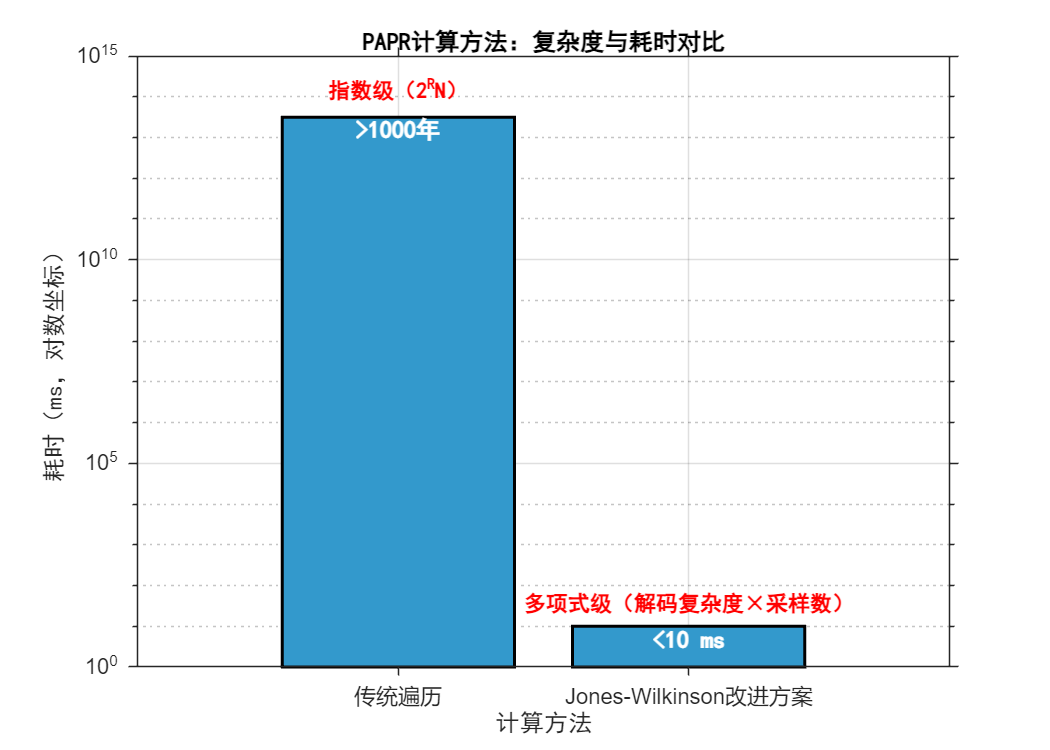

% 计算方法复杂度与耗时对比柱状图（论文创新1核心对比）
clear; clc; close all;

%% 1. 数据准备（统一单位：毫秒ms，解决量级差异）
methods = {'传统遍历', 'Jones-Wilkinson改进方案'};  % 计算方法
complexity = {'指数级（2^RN）', '多项式级（解码复杂度×采样数）'};  % 复杂度级别
% 耗时换算（统一为毫秒，突出量级差异）：
% 传统遍历：1000年 = 1000×365×24×3600×1000 ms ≈ 3.154×10^13 ms
% 论文方法：10 ms（取上限，便于可视化）
time_ms = [3.154e13, 10];  

%% 2. 绘图设置（适配PPT，突出核心差异）
figure('Position', [100, 100, 700, 500]);  % 画布大小（宽×高）
set(gcf, 'Color', 'white');  % 白色背景，适配PPT

% 绘制柱状图（对数坐标，解决量级悬殊问题）
b = bar(methods, time_ms, 'FaceColor', [0.2, 0.6, 0.8], 'EdgeColor', 'black', 'LineWidth', 1.5);
set(gca, 'YScale', 'log');  % y轴设为对数坐标，清晰展示10^13 vs 10的差异

%% 3. 标注复杂度级别（柱子上方，直观对应）
for i = 1:length(methods)
    text(i, time_ms(i)*2, complexity{i}, ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', 11, 'FontWeight', 'bold', 'Color', 'red');
end

%% 4. 标注耗时数值（柱子中部，突出量级）
text(1, time_ms(1)/2, '>1000年', ...
     'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
     'FontSize', 12, 'FontWeight', 'bold', 'Color', 'white');
text(2, time_ms(2)/2, '<10 ms', ...
     'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
     'FontSize', 12, 'FontWeight', 'bold', 'Color', 'white');

%% 5. 图形美化与坐标设置
xlabel('计算方法', 'FontSize', 14);
ylabel('耗时（ms，对数坐标）', 'FontSize', 14);
title('PAPR计算方法：复杂度与耗时对比', 'FontSize', 16, 'FontWeight', 'bold');
grid on; grid minor;  % 网格辅助观察（对数坐标下仍清晰）

% 调整y轴范围（聚焦有效区间，避免空白过多）
ylim([1, 1e15]);  % 覆盖10 ms ~ 1e15 ms（≈3万年）

% 美化坐标轴刻度与字体
set(gca, 'FontSize', 11);
set(gca, 'TickDir', 'out');  % 刻度向外，更美观
set(findall(gcf, 'Type', 'Text'), 'FontName', 'SimHei');  % 中文显示正常（避免乱码）